# Birds at risk

Determine how many birds are at risk of collision with windturbine where and when.

## Grid Information

load('../2018/data/Density_estimationMap','g');
addpath('../2018/functions/')

## Windturbine Dataopts = detectImportOptions('WT_data/TheWindPowerDatabaseWithRotorParameters04Mar_withAssumptions.csv');

t=readtable('WT_data\TheWindPowerDatabaseWithRotorParameters04Mar_withAssumptions.csv',opts);

t(isnan(t.Latitude) | isnan(t.Longitude),:)=[];

Add grid location to each windfarm and filter for windfarm further than 50km

[dist,grid_id] = min(pdist2([g.lat2D(g.latlonmask) g.lon2D(g.latlonmask)],[t.Latitude t.Longitude],@lldistkm));
t.grid_id = grid_id';
t(dist>50,:)=[];

Remove offshore turbine

t(~strcmp(t.Offshore_Shore_distance,'No'),:)=[];

Display table

t

t = 13281×34 table
    x___ID    Continent     ISO_code      Country      State_code               Area                          City                      Name                X2nd_name          Latitude    Longitude    Altitude_Depth    Location_accuracy    Offshore_Shore_distance    Manufacturer        Turbine         Hub_height    Number_of_turbines    Total_power                     Developer                                     Operator                                        Owner                        Commissioning_date        Status        Decommissioning_date   

## Assessed missing data

disp(['Missing ' num2str(sum(isnan(t.turbine_sweptArea) | isnan(t.Number_of_turbines))) ' windfarms data (out of ' num2str(size(t,1)) ,' windfarms'])

Missing 3101 windfarms data (out of 13281 windfarms


disp(['Missing ' num2str(nansum(t.Number_of_turbines(isnan(t.turbine_sweptArea)))) ' windturbines data (out of ' num2str(nansum(t.Number_of_turbines)) ,' windturbines'])

Missing 8288 windturbines data (out of 44426 windturbines


## Construct Turbine sweep area map

[G,ID] = findgroups(t.grid_id);
turbineSweptArea=nan(1,g.nlm);
turbineSweptArea(ID) = splitapply(@nansum,t.turbine_sweptArea.*t.Number_of_turbines,G);

turbineSweptAreaMap = nan(size(g.latlonmask));
turbineSweptAreaMap(g.latlonmask) = turbineSweptArea;

Display data

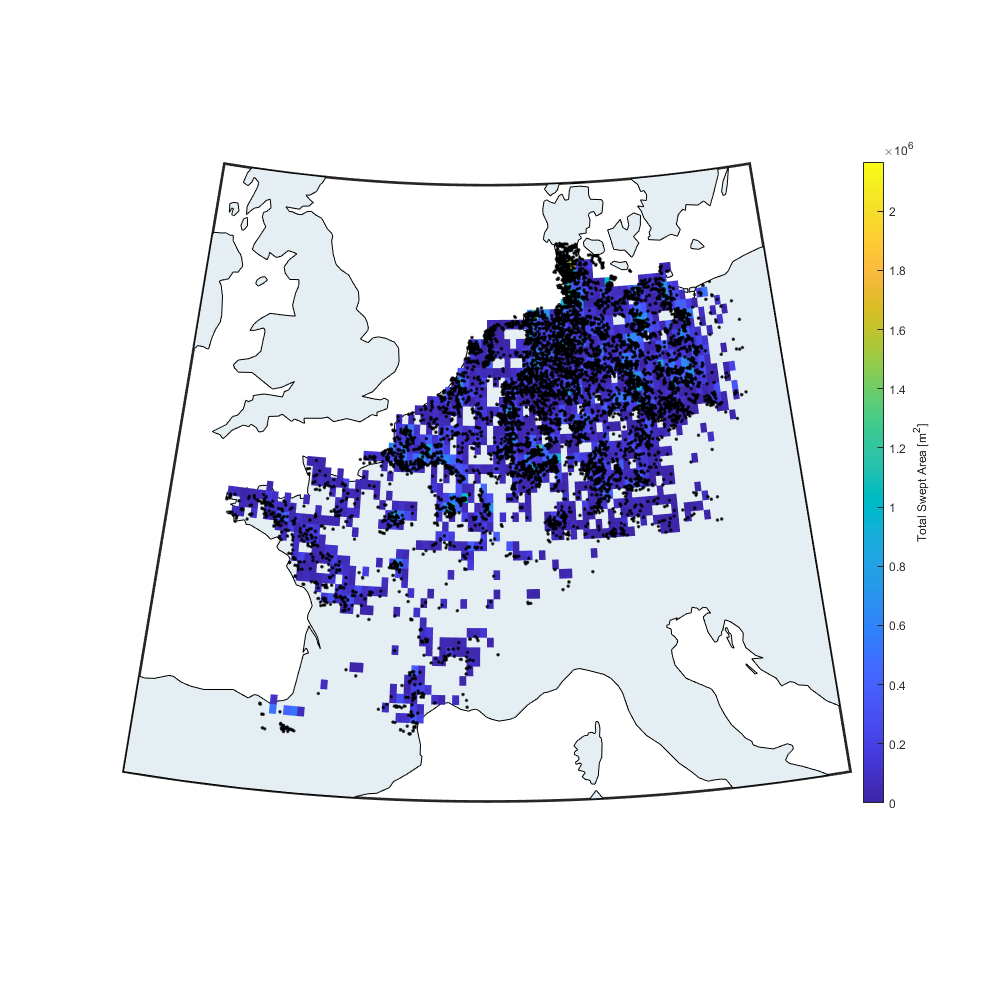

figure('position',[0 0 1000 1000]); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
surfm(g.lat,g.lon,turbineSweptAreaMap)
scatterm(t.Latitude,t.Longitude,'.k');
c=colorbar; c.Label.String='Total Swept Area [m^2]';

## Load Etimation Flow Data

load('../2018/data/Density_estimationMap','gd');
load('../2018/data/Flight_estimationMap','guv');

load the ratio map

load('./data/ratio');
%g_ratio = 0.05;

## Bird at Risk

Compute the bird at risk as


$$A_{\textrm{swept}} {\cdot N}_{\textrm{wt}} \cdot \rho \cdot r_{\textrm{wt}} \cdot h\cdot v$$


- $N_{\textrm{wt}} \cdot A_{\textrm{swept}}$: Swept area map (sum of swept are of windturbine in each grid cell) [m^2]

- $\rho$ : bird density [bird/km^2]

- $r_{\textrm{wt}}$: ratio of bird density (in bird/km^2) at windturbine elevation [-]

- $h$: height assumed when computing the ratio. []

- $v=\sqrt{v_u^2 +v_u^{2\;} }$: bird speed [m/s]

birdAtRisk = nan(g.nlat,g.nlon,g.nt);
birdAtRisk(repmat(g.latlonmask,1,1,g.nt)) = (turbineSweptArea' .* gd.dens_est * 1e-6 .* g_ratio / (windturbine_maxheight-windturbine_minheight)  .* sqrt(guv.u_est.^2 + guv.v_est.^2)*60*60); 
% m^2 * bird/km^2 * km^2/m^2 * - * 1/m * m/s * s/hr -> bird/hr
% m^2 * bird/m^2 * 1/m * m/hr -> bird/hr

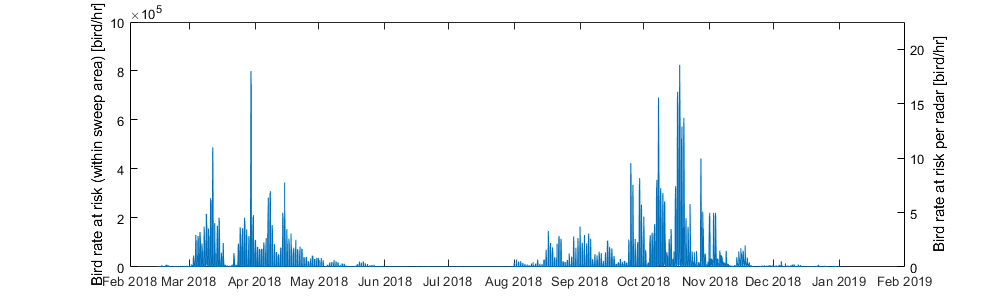

figure('position',[0 0 1000 300]); 
plot(g.time,reshape(nansum(nansum(birdAtRisk,1),2),1,[]));
ylim([0 1e6]);ylabel('Bird rate at risk (within sweep area) [bird/hr]')
yyaxis 'right'
ax = gca; ax.YAxis(2).Color = 'k';
ylim([0 1e6]/nansum(t.Number_of_turbines)); ylabel('Bird rate at risk per radar [bird/hr]')

## Simulated Bird density

Run on UNIL server

rar = nan(g.nt,500);

prepare the birdrisk template (just need to multiply by density

birdAtRisk_t = nan(g.nlat,g.nlon,g.nt);
birdAtRisk_t(repmat(g.latlonmask,1,1,g.nt)) = turbineSweptArea' * 1e-6 .* g_ratio / (windturbine_maxheight-windturbine_minheight)  .* sqrt(guv.u_est.^2 + guv.v_est.^2)*60*60; 
   

Loop through all files

for ii=1:5
    load(['D:\Guests\rafnuss_at_gmail_com\tmp_BMM2018\Density_simulationMap_reassemble_' num2str(ii)]);
    for i_real = 1:size(real_dens,4)
        rar(:, (ii-1)*100+i_real) = reshape(nansum(nansum(birdAtRisk_t .* real_dens(:,:,:,i_real),1),2),1,[]);
    end
end

Save

save('data/BirdAtRisk_sim','rar')

Load

load('data/BirdAtRisk_sim')

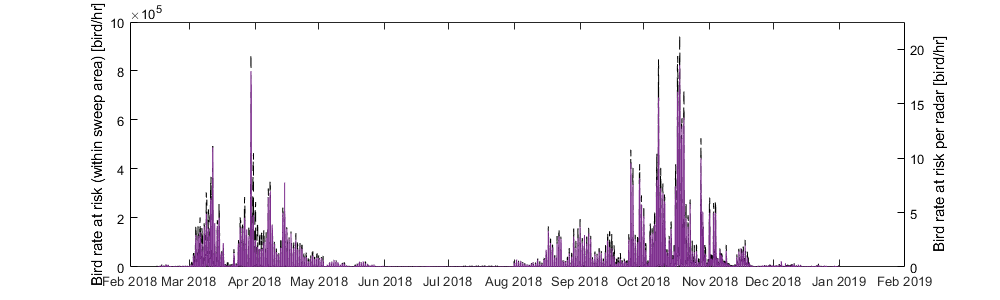

figure('position',[0 0 1000 300]);  hold on;
plot(g.time,nanmean(rar,2),'k')
plot(g.time,quantile(rar,.1,2),'--k')

plot(g.time,quantile(rar,.9,2),'--k')
plot(g.time,reshape(nansum(nansum(birdAtRisk,1),2),1,[]),'LineWidth',0.1);

ylim([0 1e6]);ylabel('Bird rate at risk (within sweep area) [bird/hr]')
yyaxis 'right'
ax = gca; ax.YAxis(2).Color = 'k'; box on
ylim([0 1e6]/nansum(t.Number_of_turbines)); ylabel('Bird rate at risk per radar [bird/hr]')

## Wind data

file='./ECMWF/2018_srf.nc'; %ncdisp(file);
wind.time = datenum('01-janv-2018'):1/24:datenum('31-dec-2018 23:00'); % ncread(file,'time')
wind.latitude=flip(double(ncread(file,'latitude')));
wind.longitude=double(ncread(file,'longitude'));
wind.u100 = permute(flip(ncread(file,'u100'),2) , [2 1 3]); 
wind.v100 = permute(flip(ncread(file,'v100'),2) , [2 1 3]);

F = griddedInterpolant({wind.latitude,wind.longitude,datenum(wind.time)},wind.u100,'nearest');
u100 = F({g.lat, g.lon, datenum(g.time)});

F = griddedInterpolant({wind.latitude,wind.longitude,datenum(wind.time)},wind.v100,'nearest');
v100 = F({g.lat, g.lon, datenum(g.time)});

uv100 = sqrt(u100.^2+v100.^2);

tmp= sqrt(wind.u100.^2 + wind.v100 .^2);

## Wind vs birdatrisk

id = ~isnan(birdAtRisk) & birdAtRisk>10;
figure;plot(birdAtRisk(id), uv100(id),'.k');
xlabel('Bird at Risk [bird/hr]')
ylabel('windspeed [m/s]')

[https://github.com/Open-Power-System-Data](https://github.com/Open-Power-System-Data) 